# Restricted Boltzmann Machine Predictor Visualizer

The purpose of this script is to help visualize the predictions made by the boltzman machine. The real data is labeled {1,-1}. Where 1 means that a student answered correctly, and -1 that the student did not. Th RBM predicts a numerical value > 0. Depending on the number of epochs trained.

## Load the Data

Here, we load the predictions of the RBM on the first training/validation set, along with the true labels.

clear variables, close all
% load the validation set
Set = readmatrix("v1.csv", "NumHeaderLines",1);
% split the labels into test and validation labels
[numRows, numCols] = size(Set);
midpoint = round(numRows/2);
valSet = Set(1:midpoint, :);
testSet = Set(midpoint + 1:end, :);
valLabel = valSet(:,3);
testLabel = testSet(:,3);
% split the predictions into validation and test
predictions  = readmatrix("preds_R1.csv", "NumHeaderLines",1);
valPred = predictions(1:midpoint, :);
testPred = predictions(midpoint + 1:end, :);

## Visualization

The data is going to be visualized.

first, lets take a look at a histogram of the predictions, along with the number of labels

numNeg = sum(valLabel(:) == -1);
numPos = size(valLabel,1) - numNeg;
PosToNegRatio = numPos /(numPos + numNeg);

What we can observe, is the ratio of '1' to the total number of predictions is 0.64. Meaning that simply always predicting '1', will be right 64% of the time. The goal is to achieve a better result.

#### Histogram

now we can visualize the spread of predictions

max1 = max(valPred);
min1  = min(valPred);
%histogram(predictions,100);
%hold off
%scatter(predictions,labels);

From the histogram and scatter plot, we can see there is no clear distinction between predictions, and that prediction labels pairs can occur at all ranges. What we can do is visualize the concentration of each label.

now we find how distributed these labels are

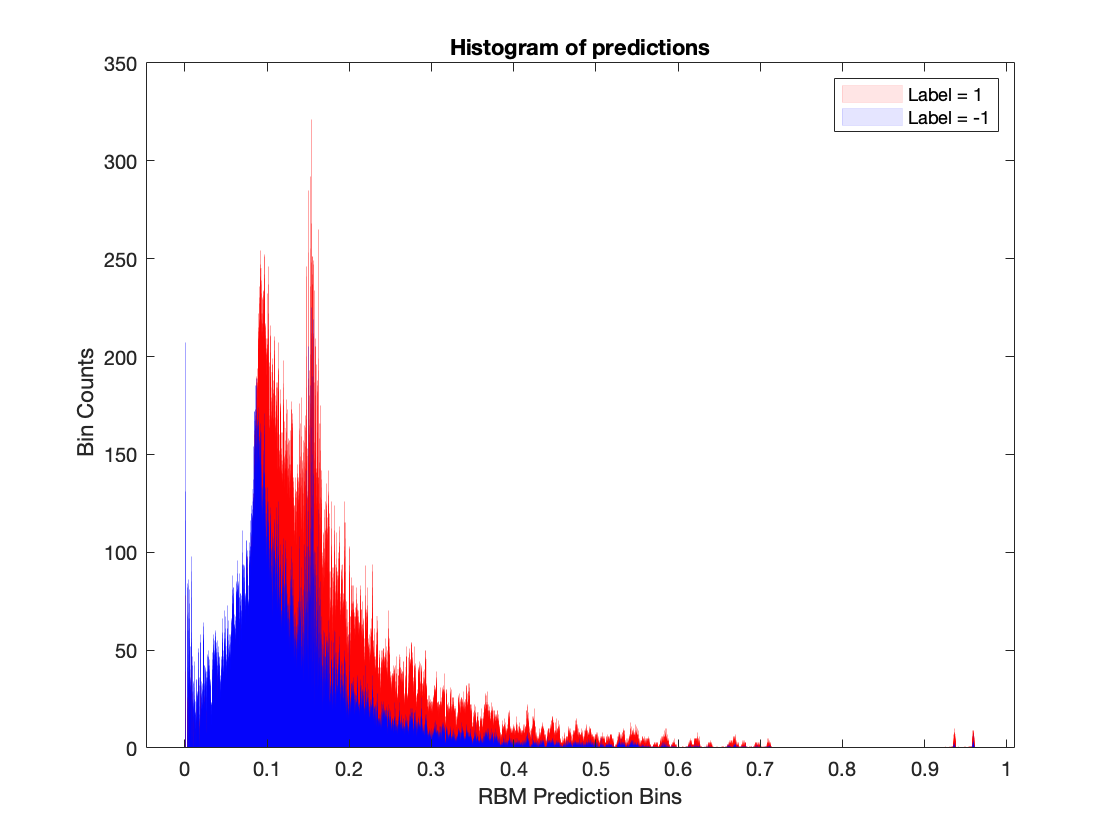

negIdx = find(valLabel == -1);
posIdx = find(valLabel == 1);

h1= histogram(valPred(posIdx),50000);
hold on
h2= histogram(valPred(negIdx),50000);
xlabel("RBM Prediction Bins")
ylabel(" Bin Counts")
title("Histogram of predictions")
legend("Label = 1", "Label = -1")

set(h1,'FaceColor','r','EdgeColor','r','EdgeAlpha',0.1,'facealpha',0.1);
set(h2,'FaceColor','b','EdgeColor','b','EdgeAlpha',0.1,'facealpha',0.1);

It can be seen that the boltzman machine is able to find a sense of biasing towards the different predictions, however, the distributions are intermixed, there is no clear distinction to be found. What we can do instead is find a prediction rule that maximizes the predictions

Now we test which threshold values can maximize the prediction on the test set

first define the thresholds:

meanTot = mean(valPred)

meanTot = 0.1529

medianTot = median(valPred)

medianTot = 0.1241

meanNeg = mean(valPred(negIdx))

meanNeg = 0.1273

medianNeg = median(valPred(negIdx))

medianNeg = 0.1047

logistic = 0.10

logistic = 0.1000

visual = 0.855

visual = 0.8550

%Thresholds = [meanTot, medianTot, meanNeg, medianNeg, logistic, visual]
Thresholds = 0.08:0.001:0.11;
% this will hold the results of prediction:
% each column: classRate, TP, TN, FP, FN
% each row is the for each threshold
Results = zeros(size(Thresholds, 1), 5);

for t = 1:size(Thresholds,2)
Results(t,:) = predict(Thresholds(t), testPred, testLabel);

end

This section defines the prediction results

function results = predict(t, pred, label)
TP = 0;
TN = 0;
FP = 0;
FN = 0;

totUsers = size(pred, 1);

for user = 1:totUsers
    
    ulabel = label(user);
    if pred(user) < t
        upred  = 0;
    else
        upred = 1;
    end
    
    if upred == 0 && ulabel == -1
        TN = TN + 1;
    elseif upred == 1 && ulabel == 1
        TP = TP + 1;
    elseif upred == 1 && ulabel == -1
        FP = FP + 1;
    elseif upred == 0 && ulabel == 1
        FN = FN + 1;
    end

end  
classRate = (TP + TN)/totUsers;
results  = [classRate , TP, TN, FP, FN] ;     
end

